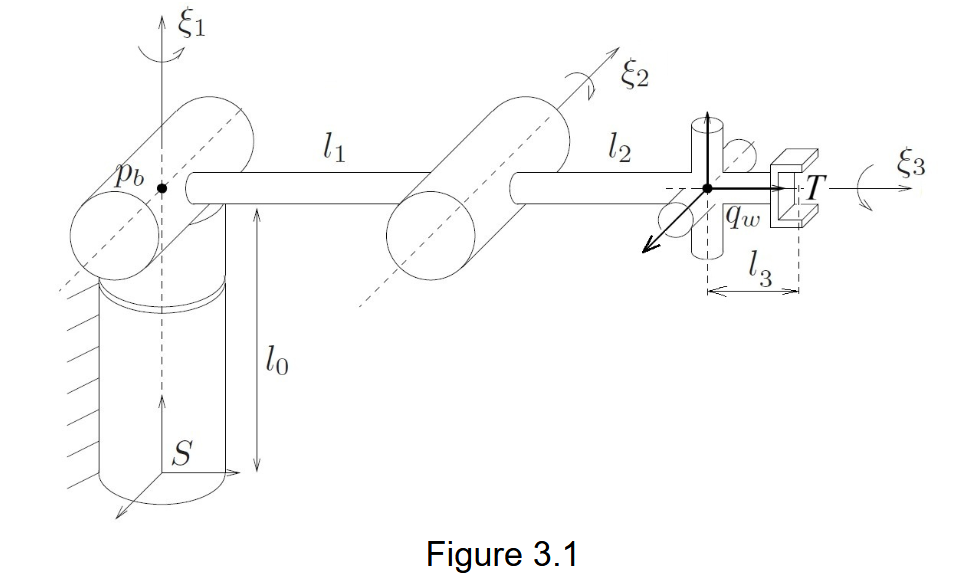

l0 = 0.65; l1 =0.8; l2 = 0.5;l3 = 0.2;
r1 = 0.5*l1;r2 = 0.5*l2; r3 = 0.5*l3;
w1 = [0;0;1];
w2 = [-1;0;0];
w3 = [0;1;0];
pb = [0;0;l0];
q1 = pb; q2 = [0;l1;l0];q3 = pb;

m1 = 70; m2 = 40;m3 = 30;

Ix1 = 4.1;
Iy1 = 0.94;
Iz1 = 5.1;
Ix2 = 2.5;
Iy2 = 0.65;
Iz2 = 2.35;
Ix3 =Ix2;
Iy3 = 0.65;
Iz3 = 2.35;


gst0 = [eye(3) [0;l1+l2+l3;l0]
        zeros(1,3)   1]

gst0 =    1.000000000000000                   0                   0                   0
                   0   1.000000000000000                   0   1.500000000000000
                   0                   0   1.000000000000000   0.650000000000000
                   0                   0                   0   1.000000000000000



xi1 = [cross(q1,w1);w1];
xi2 = [cross(q2,w2);w2];
xi3 = [cross(q3,w3);w3];
xi = [xi1,xi2,xi3];

gsl1_0 = [eye(3), [0; r1; l0];
          0 0 0 1];

gsl2_0 = [eye(3), [0; l1+r2; l0];
          0 0 0 1];
gsl3_0 = [eye(3), [0; l1+l2+r3; l0];
          0 0 0 1];
gsl0 = {gsl1_0, gsl2_0, gsl3_0};

syms th1 th2 th3 real
syms dth1 dth2 dth3 real

theta = [th1;th2;th3]

$$theta = \left(\begin{array}{c} {\mathrm{th}}_{1}\\ {\mathrm{th}}_{2}\\ {\mathrm{th}}_{3} \end{array}\right)$$

dtheta = [dth1; dth2; dth3]

$$dtheta = \left(\begin{array}{c} {\mathrm{dth}}_{1}\\ {\mathrm{dth}}_{2}\\ {\mathrm{dth}}_{3} \end{array}\right)$$


G1 = [m1 * eye(3), zeros(3,3);
      zeros(3,3), diag([Ix1, Iy1, Iz1])];

G2 = [m2 * eye(3), zeros(3,3);
      zeros(3,3), diag([Ix2, Iy2, Iz2])];

G3 = [m3 * eye(3), zeros(3,3);
      zeros(3,3), diag([Ix3, Iy3, Iz3])];
G = {G1, G2, G3};

[M, C, Jtilde_all, Gp_all] = compute_MC(xi,theta,dtheta,gsl0,G)

在当前文件夹或 MATLAB 路径中未找到 compute_MC，但它存在于:
 D:\Qi Zhang\Courses\KINE., DYN. CONTROL OF ROBOTS
    D:\Qi Zhang\Courses\KINE., DYN. CONTROL OF ROBOTS\HW7

更改 MATLAB 当前文件夹 或 将其文件夹添加到 MATLAB 路径


beta1 = 1.1; % Nms/rad
beta2 = 0.63; % Nms/rad
beta3 = 0.63;
beta = diag([beta1, beta2,beta3]);
V= m1*9.81*l0+m2*9.81*(l0-r2*sin(th2))+ m3*9.81*(l0-(l2+r3)*sin(th2))
N = jacobian(V,theta).' + beta*dtheta

matlabFunction(M, 'File', 'calc_M_25_b', 'Vars', {theta});
matlabFunction(C, 'File', 'calc_C_25_b', 'Vars', {theta, dtheta});
matlabFunction(N, 'File', 'calc_N_25_b', 'Vars', {theta, dtheta});
